# Figure 4

Reproduces Figure 4 and computes the VaR-loss functions in usedTable 4.

## Import data

%% Setup the Import Options
opts = spreadsheetImportOptions("NumVariables", 361);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:MW8775";

% Specify column names and types
opts.VariableNames = ["Date", "M1", "M2", "M3", "M4", "M5", "M6", "M7", "M8", "M9", "M10", "M11", "M12", "M13", "M14", "M15", "M16", "M17", "M18", "M19", "M20", "M21", "M22", "M23", "M24", "M25", "M26", "M27", "M28", "M29", "M30", "M31", "M32", "M33", "M34", "M35", "M36", "M37", "M38", "M39", "M40", "M41", "M42", "M43", "M44", "M45", "M46", "M47", "M48", "M49", "M50", "M51", "M52", "M53", "M54", "M55", "M56", "M57", "M58", "M59", "M60", "M61", "M62", "M63", "M64", "M65", "M66", "M67", "M68", "M69", "M70", "M71", "M72", "M73", "M74", "M75", "M76", "M77", "M78", "M79", "M80", "M81", "M82", "M83", "M84", "M85", "M86", "M87", "M88", "M89", "M90", "M91", "M92", "M93", "M94", "M95", "M96", "M97", "M98", "M99", "M100", "M101", "M102", "M103", "M104", "M105", "M106", "M107", "M108", "M109", "M110", "M111", "M112", "M113", "M114", "M115", "M116", "M117", "M118", "M119", "M120", "M121", "M122", "M123", "M124", "M125", "M126", "M127", "M128", "M129", "M130", "M131", "M132", "M133", "M134", "M135", "M136", "M137", "M138", "M139", "M140", "M141", "M142", "M143", "M144", "M145", "M146", "M147", "M148", "M149", "M150", "M151", "M152", "M153", "M154", "M155", "M156", "M157", "M158", "M159", "M160", "M161", "M162", "M163", "M164", "M165", "M166", "M167", "M168", "M169", "M170", "M171", "M172", "M173", "M174", "M175", "M176", "M177", "M178", "M179", "M180", "M181", "M182", "M183", "M184", "M185", "M186", "M187", "M188", "M189", "M190", "M191", "M192", "M193", "M194", "M195", "M196", "M197", "M198", "M199", "M200", "M201", "M202", "M203", "M204", "M205", "M206", "M207", "M208", "M209", "M210", "M211", "M212", "M213", "M214", "M215", "M216", "M217", "M218", "M219", "M220", "M221", "M222", "M223", "M224", "M225", "M226", "M227", "M228", "M229", "M230", "M231", "M232", "M233", "M234", "M235", "M236", "M237", "M238", "M239", "M240", "M241", "M242", "M243", "M244", "M245", "M246", "M247", "M248", "M249", "M250", "M251", "M252", "M253", "M254", "M255", "M256", "M257", "M258", "M259", "M260", "M261", "M262", "M263", "M264", "M265", "M266", "M267", "M268", "M269", "M270", "M271", "M272", "M273", "M274", "M275", "M276", "M277", "M278", "M279", "M280", "M281", "M282", "M283", "M284", "M285", "M286", "M287", "M288", "M289", "M290", "M291", "M292", "M293", "M294", "M295", "M296", "M297", "M298", "M299", "M300", "M301", "M302", "M303", "M304", "M305", "M306", "M307", "M308", "M309", "M310", "M311", "M312", "M313", "M314", "M315", "M316", "M317", "M318", "M319", "M320", "M321", "M322", "M323", "M324", "M325", "M326", "M327", "M328", "M329", "M330", "M331", "M332", "M333", "M334", "M335", "M336", "M337", "M338", "M339", "M340", "M341", "M342", "M343", "M344", "M345", "M346", "M347", "M348", "M349", "M350", "M351", "M352", "M353", "M354", "M355", "M356", "M357", "M358", "M359", "M360"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
%LWdailyMR2 = readtable("C:\Temp\LW\LW_daily_MR2.xlsx", opts, "UseExcel", false);
%LWdailyMR2 = readtable("LW_daily_MR2.xlsx", opts, "UseExcel", false);

LWdailyMR2 = readtable("LW_daily_MR3.xlsx", opts, "UseExcel", false); %outlier corrected 30y 

% Convert to output type
LWdailyMR2 = table2array(LWdailyMR2);

% Clear temporary variables
clear  opts

% arrange matrices
d = LWdailyMR2(:,1); % datevector
y = LWdailyMR2(:,2:end)/100; % yield matrix
[rows, cols] = size(y);

## Compute historical bond prices and returns

% bond prices and returns
[~,M] = meshgrid(1900:1929, 1:360); T= (M/12); T = T(:,1)'; Tmat = repmat(T,rows,1); % matrix of years to maturity
zcbondprices = 100*exp(-y.*Tmat); % matrix of zero coupon bond prices
zcbondreturns = tick2ret(zcbondprices,'method','Continuous')*100; % matrix of zero coupon bond log-returns

## Historical simulation

% set weights for simulated portfolio
weigths = zeros(rows-1,cols); % initialize
weigths(:,3)=0.20; weigths(:,12)=0.20; weigths(:,60)=0.20; weigths(:,120)=0.20; weigths(:,360)=0.20; % portfolio weights
pret = zcbondreturns.*weigths; % matrix of weighted returns
pretdaily = sum(pret, 2); % sum of weighted returns over rows (pr day)
pretdaily = pretdaily(1:end-260,:);
writematrix(pretdaily,'pretdaily.csv')

% parameters for historical simulation
quantileVec=[0.01 0.025 0.05 0.95 0.975 0.99];
qVecSize = size(quantileVec);

% historical simulation of portfolio returns
w=4000; % length of historical simulation window
historicalsimulations = zeros(rows-w-1,qVecSize(2));
counter = 0;
for i = w:rows-2-260
counter = counter+1;
    rvec = pretdaily(counter+1:(w+counter));
    historicalsimulations(counter,:)= quantile(rvec,quantileVec);
end

% remove last observations as per rest of paper
historicalsimulations = historicalsimulations(1:end-260,:);
writematrix(historicalsimulations,'historicalsimulations.csv')

## PCA-QREG

% import estimated distributions
M3 = distOOS('dist_OOS_3M.csv');
Y1 = distOOS('dist_OOS_1Y.csv');
Y5 = distOOS('dist_OOS_5Y.csv');
Y10 = distOOS('dist_OOS_10Y.csv');
Y30 = distOOS('dist_OOS_30Y.csv');

% parameters
[a,aa] = size(M3);
[b,~] = size(y);
yOOS = y((b-a:b),:);
bondsOOS = zcbondprices((b-a:b),:);

% compute quantile yields
for i = 1:a
    for j=1:aa
        sim3m(i,j) = yOOS(i,3)*exp(M3(i,j));
        sim1y(i,j) = yOOS(i,12)*exp(Y1(i,j));
        sim5y(i,j) = yOOS(i,60)*exp(Y5(i,j));
        sim10y(i,j) = yOOS(i,120)*exp(Y10(i,j));
        sim30y(i,j) = yOOS(i,360)*exp(Y30(i,j));
        
   end
end

% compute bond prices
sim3mb = 100*exp(-sim3m*(3/12));
sim1yb = 100*exp(-sim1y*(12/12));
sim5yb = 100*exp(-sim5y*(60/12));
sim10yb = 100*exp(-sim10y*(120/12));
sim30yb = 100*exp(-sim30y*(360/12));


% compute bond log-returns
for i = 1:a
    for j=1:aa
        sim3mret(i,j) = log(sim3mb(i,j))-log(bondsOOS(i,3));
        sim1yret(i,j) = log(sim1yb(i,j))-log(bondsOOS(i,12));
        sim5yret(i,j) = log(sim5yb(i,j))-log(bondsOOS(i,60));
        sim10yret(i,j) = log(sim10yb(i,j))-log(bondsOOS(i,120));
        sim30yret(i,j) = log(sim30yb(i,j))-log(bondsOOS(i,360));
   end
end

% weighted portfolio returns
wp =0.2*100*(sim3mret+sim1yret+sim5yret+sim10yret+sim30yret);

VaRPCAQREG = wp(:,[1:3,21:23]);
VaRPCAQREG = wp(:,[23,22,21,3,2,1]);
writematrix(VaRPCAQREG,'VaRPCAQREG.csv')

## Figure 4

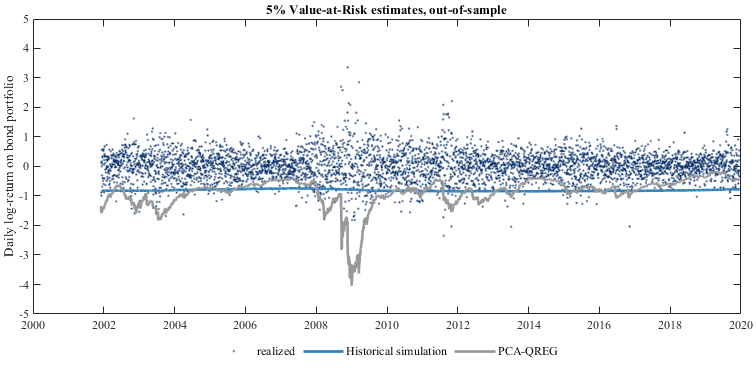

HS=readmatrix('historicalsimulations.csv');
PCAQREG=readmatrix('VaRPCAQREG.csv');
retsOOS=readmatrix('OOSrets.csv');
EstimationDates = datenum(num2str(LWdailyMR2(:,1)), 'yyyymmdd');
fig=figure;
set(fig,'DefaultAxesColorOrder',brewermap(NaN,'MRBlue3Green3Red3'))


%subplot(1,2,1)
plot(EstimationDates(4002:8514),retsOOS,'.','MarkerSize',3,'MarkerFaceColor',[0.5, 0.5, 0.5])
datetick
hold on
plot(EstimationDates(4002:8514),HS(:,3),'-','LineWidth',2)
plot(EstimationDates(4002:8514),PCAQREG(:,3),'-','LineWidth',2)
ylim([-5 5])
ylabel('Daily log-return on bond portfolio')
title('5% Value-at-Risk estimates, out-of-sample')
legend({'realized','Historical simulation','PCA-QREG'},'location','southoutside','orientation','horizontal')
legend('boxoff') 
opts.saveFolder = '';
opts.width      = 20;
opts.height     = 10;
opts.fontType   = 'Times';
opts.fontSize   = 9;

% scaling
fig.Units               = 'centimeters';
fig.Position(3)         = opts.width;
fig.Position(4)         = opts.height;

% set text properties
set(fig.Children, ...
    'FontName',     'Times', ...
    'FontSize',     9);

% remove unnecessary white space
set(gca,'LooseInset',max(get(gca,'TightInset'), 0.02))

## VaR Losses OOS used in Table 4

tauVec = [0.01 0.025 0.05 0.95 0.975 0.9];
r = 0.010; %cost of capital
BetaParam = (r/365);
ind=3;

[VaRLossHS] = VaRLosses(pretdaily(4001:8513),tauVec, historicalsimulations, BetaParam);
[VaRLossPCAQREG] = VaRLosses(pretdaily(4001:8513),tauVec, VaRPCAQREG, BetaParam);
writematrix(VaRLossHS.ALOSS,'VaRHSLOSS.csv')
writematrix(VaRLossPCAQREG.ALOSS,'VaRPCAQREGLOSS.csv')
writematrix(pretdaily(4001:8513),'OOSrets.csv')